This is Henrik Barck's live script to teach you how to use BSFK for free knot spline fitting. 

I was investigating this to analyze camera footage of a band unloading. Thus, we will look at some sample data that starts not moving and then accelerates and then decelerates.

t=linspace(0,2*pi,30);
x=zeros(1,30);
for i=16:30
    x(i) = cos(t(i))+1;
end
y=x; %save the underlying motion in y for later

Now lets add some noise (ideally your experiment should have less noise than this but its good to practice with bad scenarios).

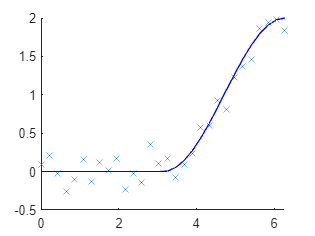

noise = 0.12* randn(1,30);
k=1;
for i = noise
    x(k) = x(k) + i;
    k=k+1;
end
figure();
hold on
plot(t,x,'x')
plot(t,y,'Color',[0, 0, 1, 0.4])

Now we want to use the BSFK package to fit a spline through our data! BSFK will return a polynomial object of the fit.

pp = BSFK(t,x,6,20,[])

pp = struct with fields:
      form: 'pp'
    breaks: [0 0.6283 0.9425 1.2566 1.5708 2.5133 2.8274 3.1416 4.3982 5.0265 6.2832]
     coefs: [10×6 double]
    pieces: 10
     order: 6
       dim: 1


In the first 3 arguements, we gave it our x axis data (t), y data (x), and told it we want a 6th order polynomial fit (a_1*x^0 + ... + a_6*x^5). 

The next field is nknots which is how BSFK distributes its knots initially. If you give a number it will evenly space that many of them across your data range or you can give it an array of numbers representing how many knots to evenly space between each fixed knot.

The next field which we left empty with [] is your fixed knots! If there is somewhere you think it's important to fix a knot, put its x axis value there. Or use this to distribute more knots in certain places with nkots as an array.

Now lets get into the fun special options for BSFK.

The last argument for BSFK is options and you can go read the documentation for all of them, but in this script I will go over the important ones in my opinion.

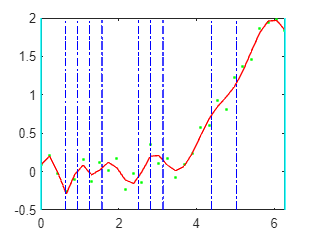

options = struct('regmethod', 'discrete', 'animation', 1 );
pp = BSFK(t,x,6,20,[], options);

options is a structure object which works kind of like a dictionary (but you can have multiple dimensions). Here I set the regmethod to discrete (default is continuous which is unnecessarily granular and takes too long) and animation to 1 which will now animate the BSFK process (this is great for debugging!)

There is also a 'waitbar' option to add a waitbar when animating, but I didnt find that very useful. 

Next we come to the option 'd' this basically asks you if you want to punish the BSFK algorithmn for using powers higher than d. lambda is also a parameter you can set and they factor into this equation: J(s) = Chi^2 + lambda*(integral from 0 to 1 (dth derivative of the spline) )^2

J(s) is basically trying to be minimized for each given spline "s" that the algorithmn tests. As an example, if you set d to 3 you are removing up to x^2 terms from the cost equation and punishing anything higher. BUT BEWARE OF LAMBDA! If you start increasing d, that integral will start getting big really fast because of power rule so you need to start decreasing lambda. (d is defualted to 2 and lambda to 0).

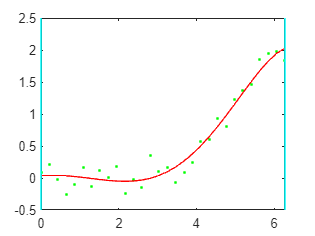

options = struct('d',3, 'lambda', 0.000001, 'regmethod', 'discrete', 'animation', 1);
pp = BSFK(t,x,6,20,[],options);

Thats much better already! we can also further customize this with more options. 

the 'knotremoval_factor' is a number greater than 1 (default 1.125) that determines how easily BSFK decides knots are not useful. Smaller value mean it wants to keep knots more.

'sigma' controls when BSFK decides the fit is good (if RMS of residuals <sigma). they recommend setting this to your noise SD or letting BSFK calculate it by default.

Below I make the knotremoval_factor smaller so that we keep more knots and set sigma to our noise SD from above.

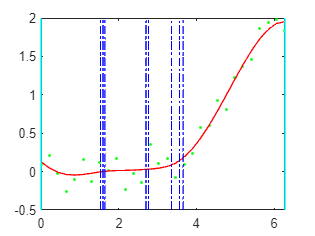

options = struct('d',3, 'lambda', 0.000001, 'sigma', 0.12, 'regmethod', 'discrete', 'knotremoval_factor', 1.01, 'animation', 1);
pp = BSFK(t,x,6,20,[],options);

Finally you may want to tell BSFK that we already know a little bit about our data's shape. 

'shape' will constrain the pth order term between lower and upper bounds: 'lo' and 'up' 

shape is also a structure so you could limit the 1st derivative with shape(0) = struct('p', 1, 'lo', 0, 'up', 10) and the 2nd derivative with shape(1) = struct('p', 2, 'lo', 0, 'up', 1). This is where structures being different from a dictionary is useful bc you can have multiple structures in it. 

If you want different contraints for different areas you can make 'lo' and 'up' arrays where each element is the constraints for the i-th knot.

If you want constrains on certain points instead of certain knots, just use the pointwise constraint option! 'pntcon'

'pntcon' takes a structure with the polynomial order to constrain, 'p', the x axis point where you want to constrain, 'x', and the value you want to constrain that polynomial order to, 'v'.

In the example below we want the second x axis point to have a slope of 0 using 'pntcon' since we know our elastic band starts at rest

and the entire plot to have a positive slope throughout using 'shape' since our elastic band is unloading the whole time. 

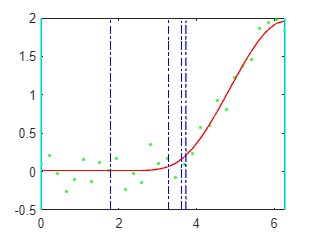

pntcon = struct('p',1,'x',t(2),'v',0);
lo = 0;
up = +inf;
shape = struct('p', 1, 'lo', lo, 'up', up);
options = struct('d',3, 'lambda', 0.000001, 'sigma', 0.12, 'regmethod', 'discrete', 'knotremoval_factor', 1.01, 'animation', 1, 'shape', shape, 'pntcon', pntcon);
pp = BSFK(t,x,6,20,[],options);

A few closing notes are:

you can set BSFK to not remove any knots at all, just move them around, with ('KnotRemoval', 'none') in options

you can set 'periodic' to true in options if your data is periodic and you want the left and right side of your data to match into each other

you can set a maximum iterations with ('maxiter', 50) in options    (the default is 100)

and you can use the pp object to do data analysis!

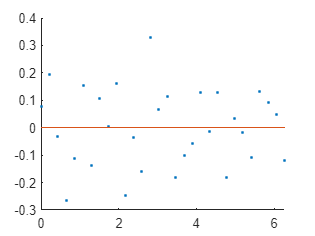

figure();
hold on
plot(t,x-ppval(pp,t),'.'); %residual plot of the polynomial to our data with noise; ppval() populates x axis data with a give polynomial object
plot([t(1) t(end)],[0 0],'-')

A final comment is that sometimes BSFK likes to put a few knots right next to each other which macroscopically doesn't make any sense. My best guess is that somehow the addition of knots right next to each other made smoothing between splines easier in a way that reduced the residuals enough to warrant knot removing the knots. This could be still something to look further into though. 